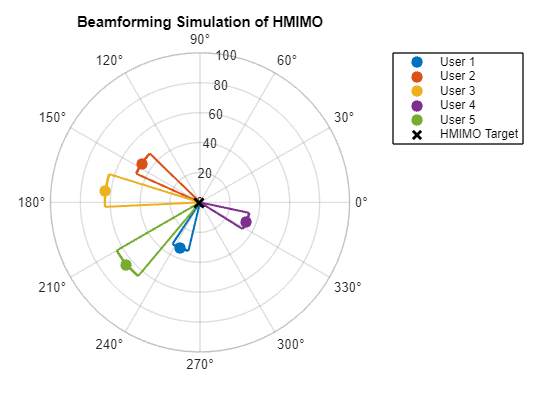

% Holographic MIMO (HMIMO) Simulation with Beamforming Visualization
clc; clear; close all;

% Parameters
numUsers = 5;             % Number of users
maxDistance = 100;        % Max distance for users (meters)
minDistance = 10;         % Min distance for users (meters)
angleRange = 360;         % Range of angles for users (degrees)
frequency = 28e9;         % Carrier frequency (Hz)
c = 3e8;                  % Speed of light (m/s)
wavelength = c / frequency; % Wavelength (meters)
beamWidth = 20;           % Beamwidth for beamforming (degrees)

% HMIMO target location (fixed at origin)
targetAngle = 0;
targetDistance = 0; % HMIMO at origin (0,0)

% Generate random positions for users (random angles and distances)
angles = angleRange * rand(1, numUsers) - angleRange / 2; % angles between -180 and +180 degrees
distances = minDistance + (maxDistance - minDistance) * rand(1, numUsers); % random distances

% Plot HMIMO target
figure;
polarplot(deg2rad(targetAngle), targetDistance, 'kx', 'MarkerSize', 10, 'LineWidth', 2); % HMIMO target
hold on;

% Colors for each user
colors = lines(numUsers);

% Array to store plot handles for legend
legendHandles = gobjects(numUsers + 1, 1);
legendLabels = cell(numUsers + 1, 1);

% Loop through users and plot lobes
for userIdx = 1:numUsers
    userAngle = angles(userIdx);
    userDistance = distances(userIdx);

    % Define angular spread around the user
    thetaSpread = linspace(deg2rad(userAngle - beamWidth / 2), deg2rad(userAngle + beamWidth / 2), 50);

    % Plot beam lobe as an outline (only lines from HMIMO to user)
    polarplot([thetaSpread(1) thetaSpread(1)], [0 userDistance], 'Color', colors(userIdx, :), 'LineWidth', 1.5); % Line-drawn beams (no fill)
   
    % Define radial distance: fixed for outer edge and starting from 0 for inner edge
    rOuter = userDistance * ones(size(thetaSpread));
    rInner = zeros(size(thetaSpread)); % Start from HMIMO

    % Plot the outer curved edge of the lobe
    polarplot(thetaSpread, rOuter, 'Color', colors(userIdx, :), 'LineWidth', 2); % Curved edge

    % Plot straight lines from HMIMO to the user for the lobe's sides
    polarplot([deg2rad(userAngle - beamWidth / 2), deg2rad(userAngle + beamWidth / 2)], [0, userDistance], 'Color', colors(userIdx, :), 'LineWidth', 1.5); % Lobe sides
    hold on;

    % Plot the user as a dot with color fill
    legendHandles(userIdx) = polarplot(deg2rad(userAngle), userDistance, 'o', 'MarkerSize', 8, 'MarkerFaceColor', colors(userIdx, :), 'MarkerEdgeColor', colors(userIdx, :));

    % Store label for the legend
    legendLabels{userIdx} = ['User ' num2str(userIdx)];
end

% Plot HMIMO target
legendHandles(end) = polarplot(deg2rad(targetAngle), targetDistance, 'kx', 'MarkerSize', 10, 'LineWidth', 2);
legendLabels{end} = 'HMIMO Target';

% Add the legend and set its position outside the plot
legend(legendHandles, legendLabels, 'Location', 'northeastoutside');

% Add title and customize plot
title('Beamforming Simulation of HMIMO');
rlim([0 maxDistance]);

hold off;